% 1st order
clc; clear; close all
tic
format long

%% parameter settings
tol = 1e-5;
kmax = 3000;
N = 129;
x = linspace(-1, 1, N);
z = linspace(-1, 1, N);
[X, Z] = meshgrid(x, z);

%% examples
c_exact = 3 - 2.5 * exp(-X.^2 / 2);
% c_exact = ones(N);
% c_exact = 3 - (1/2)*exp(-(X.^2 + (Z-0.5).^2)/0.5.^2) - exp(-(X.^2 + (Z-1.25).^2)/0.5.^2);
% load c_data/example_4
% load D:\桌面\codes\examples&results\results\example_4\c

%% source point
fixed_pt_list = [];
for n = 1:4
    fixed_pt_list = [fixed_pt_list; 0, 20, n*25];
    fixed_pt_list = [fixed_pt_list; 0, N-19, n*25];
    fixed_pt_list = [fixed_pt_list; 0, n*25, 20];
    fixed_pt_list = [fixed_pt_list; 0, n*25, N-19];
end   


%% iteration
I = N;
J = N;
dx = (x(end)-x(1)) / (I-1); dy = (z(end) - z(1)) / (J-1);

niu = 1;
c0 = c_solver2(c_exact, zeros(I, J), dx, dy, niu);
c = c0;

energy = 1e9;
relative_error = 1e9;
% alpha_f = 1e-4; alpha_0 = 0.1;
for k = 1: kmax
    
    energy_p = 0;
    cstar = 0;
    parfor p_num = 1:size(fixed_pt_list, 1)
        T = TravelTime_solver(c, fixed_pt_list(p_num, :), dx, dy, I, J);
        T_star = TravelTime_solver(c_exact, fixed_pt_list(p_num, :), dx, dy, I, J);
        energy_p = energy_p + EnergyFun(T, T_star, dx, dy);
        cstar = cstar + cStarSolver(T, T_star, dx, I, J, c);
    end
    
    if norm(cstar)*dx*dy < tol
        break
    end

    energy = [energy, energy_p];
    relative_error = [relative_error, norm(c-c_exact)/norm(c_exact)];
    if mod(k, 10) == 0
       disp(k)
       disp(norm(cstar)*dx*dy)
    end

        alpha = 0.01;
%     alpha = alpha_f + 0.5*(alpha_0 - alpha_f) * (1 + cos(pi*k / kmax));
    c = c + alpha * cstar;
   
end

    10


   0.025314159411588


    20


     4.566024838819612e-04


    30


     2.714585526838768e-04


    40


     1.543681590389563e-04


    50


     8.722276671278678e-05


    60


     4.951890627120006e-05


    70


     4.328349156763241e-05


    80


     4.204943142949832e-05


    90


     4.112570403026429e-05


   100


     4.035769820841390e-05


   110


     3.967773038705800e-05


   120


     3.904438265311341e-05


   130


     3.844006467275610e-05


   140


     3.785577086436303e-05


   150


     3.728686297095160e-05


   160


     3.673085752072902e-05


   170


     3.618615166840465e-05


   180


     3.565189270953759e-05


   190


     3.512743065296646e-05


   200


     3.461248970543717e-05


   210


     3.410689613854021e-05


   220


     3.361028978707128e-05


   230


     3.312239726165922e-05


   240


     3.264313190439545e-05


   250


     3.217146844839100e-05


   260


     3.170885493381454e-05


   270


     3.125438555495319e-05


   280


     3.080781859431565e-05


   290


     3.036904176520094e-05


   300


     2.993797284513697e-05


   310


     2.951447168830855e-05


   320


     2.909835314035046e-05


   330


     2.868951000076842e-05


   340


     2.828785130472660e-05


   350


     2.789326071386662e-05


   360


     2.750560988332563e-05


   370


     2.712478338738476e-05


   380


     2.675066889086037e-05


   390


     2.638315234417559e-05


   400


     2.602167846156489e-05


   410


     2.566635236416749e-05


   420


     2.531752214296729e-05


   430


     2.497513025219142e-05


   440


     2.463863762965092e-05


   450


     2.430567925047502e-05


   460


     2.398137197289471e-05


   470


     2.366256288136503e-05


   480


     2.334927497004241e-05


   490


     2.304027354669471e-05


   500


     2.273605808964073e-05


   510


     2.243900170932596e-05


   520


     2.214713709183108e-05


   530


     2.186036729858318e-05


   540


     2.157858760038538e-05


   550


     2.130174094779135e-05


   560


     2.102973363664661e-05


   570


     2.076247913196692e-05


   580


     2.049989612067095e-05


   590


     2.024190040011612e-05


   600


     1.998840182166103e-05


   610


     1.973931652952349e-05


   620


     1.949401853602655e-05


   630


     1.925347316136845e-05


   640


     1.901708906146057e-05


   650


     1.878478981285420e-05


   660


     1.855649754237343e-05


   670


     1.833213574404333e-05


   680


     1.811162756902915e-05


   690


     1.789489643855578e-05


   700


     1.768187370372984e-05


   710


     1.747246736855724e-05


   720


     1.726659233622144e-05


   730


     1.706417882247623e-05


   740


     1.686474191251789e-05


   750


     1.666902166301143e-05


   760


     1.647653119863746e-05


   770


     1.628721942630650e-05


   780


     1.610107187583792e-05


   790


     1.591801635450039e-05


   800


     1.573762933494118e-05


   810


     1.556059134221497e-05


   820


     1.538645354521327e-05


   830


     1.521517861195708e-05


   840


     1.504671207944971e-05


   850


     1.488099818436832e-05


   860


     1.471798164144598e-05


   870


     1.455761274292810e-05


   880


     1.439983755795037e-05


   890


     1.424460518285785e-05


   900


     1.409186551486253e-05


   910


     1.394156239234204e-05


   920


     1.379364941724323e-05


   930


     1.364807923183356e-05


   940


     1.350481024959924e-05


   950


     1.336379659644878e-05


   960


     1.322499378931340e-05


   970


     1.308835830333661e-05


   980


     1.295384654681546e-05


   990


     1.282140939228680e-05


        1000


     1.269099612414906e-05


        1010


     1.256258488913174e-05


        1020


     1.243613847245495e-05


        1030


     1.231160152766056e-05


        1040


     1.218893811898622e-05


        1050


     1.206811149123927e-05


        1060


     1.194908621691359e-05


        1070


     1.183182645150472e-05


        1080


     1.171630520155131e-05


        1090


     1.160248102375883e-05


        1100


     1.149031754967794e-05


        1110


     1.137978631445218e-05


        1120


     1.127086111599133e-05


        1130


     1.116350613039760e-05


        1140


     1.105769563172654e-05


        1150


     1.095340374689384e-05


        1160


     1.085060071769779e-05


        1170


     1.074926057047268e-05


        1180


     1.064935518942349e-05


        1190


     1.055085726373968e-05


        1200


     1.045373985160074e-05


        1210


     1.035797151882201e-05


        1220


     1.026350312412684e-05


        1230


     1.017033814413756e-05


        1240


     1.007845331319894e-05



%% results and visualization
norm(c-c_exact)*dx*dx

ans =      1.593244872070723e-04

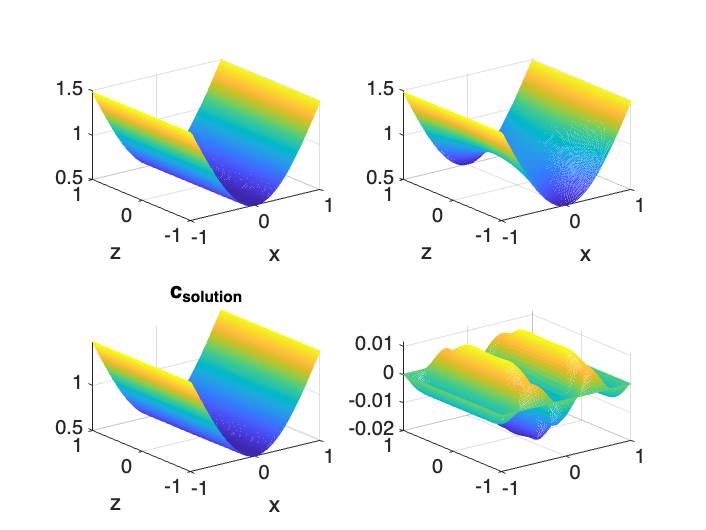


figure
subplot(2, 2, 1)
mesh(x, z, c_exact)
xlabel x
ylabel z
% title('c_{exact}', 'FontWeight','bold')
subplot(2, 2, 2)
mesh(x, z, c0)
xlabel x
ylabel z
% title('c_0', 'FontWeight','bold')
subplot(2, 2, 3)
mesh(x, z, c)
xlabel x
ylabel z
title('c_{solution}', 'FontWeight','bold')
subplot(2, 2, 4)
mesh(x, z, (c-c_exact)./c_exact)

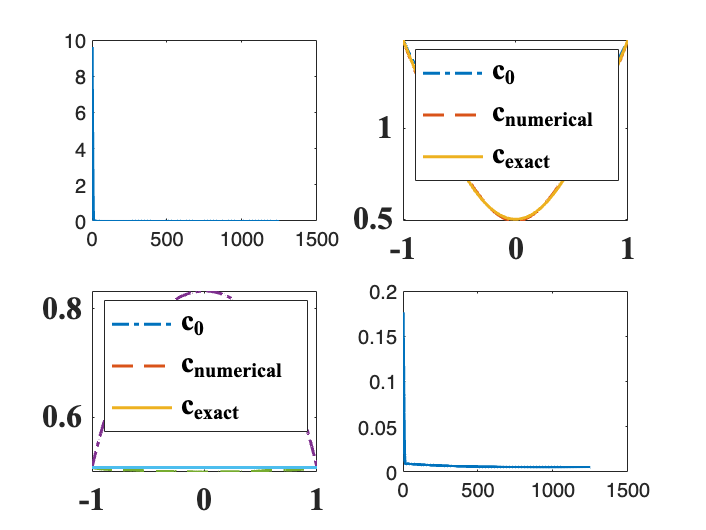

% title('Relative error')

figure
subplot(2, 2, 1)
plot(energy(2:end), 'linewidth', 1.5)
% title('Energy')

subplot(2, 2, 2)
plot(z, c0(60, :), '-.', 'linewidth', 1.5)
hold on
plot(z, c(60, :), '--', 'linewidth', 1.5)
hold on
plot(z, c_exact(60, :), 'linewidth', 1.5)
legend('c_0', 'c_{numerical}', 'c_{exact}')
% title('Cross-sections of the solutions: x = 0', 'FontWeight','bold')
set(gca, 'FontName','Times New Roman', 'FontSize',16, 'FontWeight','bold');

subplot(2, 2, 3)
plot(x, c0(:, 60), '-.', 'linewidth', 1.5)
hold on
plot(x, c(:, 60), '--', 'linewidth', 1.5)
hold on
plot(x, c_exact(:, 60), 'linewidth', 1.5)
legend('c_0', 'c_{numerical}', 'c_{exact}')
% title('Cross-sections of the solutions: z = 0', 'FontWeight','bold')
set(gca, 'FontName','Times New Roman', 'FontSize',16, 'FontWeight','bold');

subplot(2, 2, 3)
plot(x, c0(:, 60), '-.', 'linewidth', 1.5)
hold on
plot(x, c(:, 60), '--', 'linewidth', 1.5)
hold on
plot(x, c_exact(:, 60), 'linewidth', 1.5)
legend('c_0', 'c_{numerical}', 'c_{exact}')
% title('Cross-sections of the solutions: z = 0', 'FontWeight','bold')
set(gca, 'FontName','Times New Roman', 'FontSize',16, 'FontWeight','bold');
subplot(2, 2, 4)
plot(relative_error(2:end), 'linewidth', 1.5)

% title('Relative error')
toc

历时 302.368905 秒。
